5.2.1

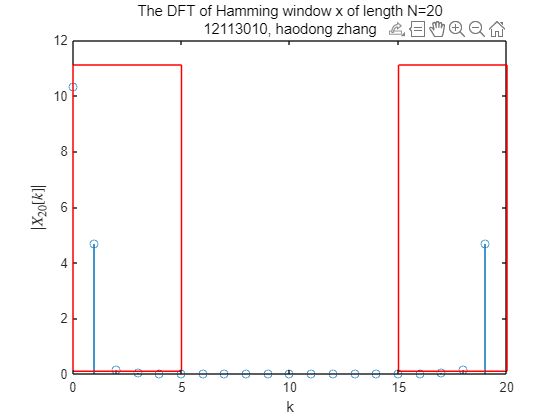

N = 20;
x = hamming(20);
k = 0:N-1;
X = DFTsum(x');
stem(k,abs(X));
hold on
rectangle('Position', [0, 0.1, 5, 11], 'EdgeColor', 'r');
hold on
rectangle('Position', [15, 0.1, 5, 11], 'EdgeColor', 'r');
hold off;
title(sprintf('The DFT of Hamming window x of length N=20\n12113010, haodong zhang'))
xlabel('k');
ylabel('$\left | X_{20}[k]  \right | $', 'Interpreter', 'latex')

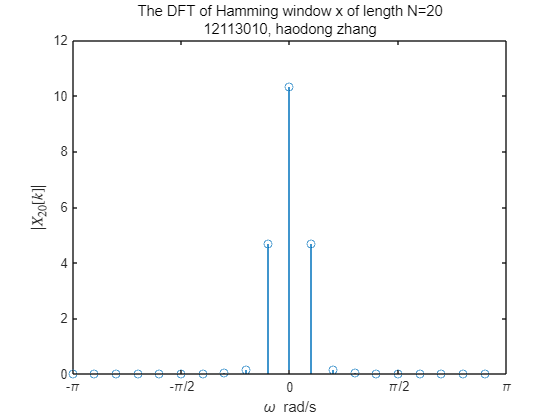


[X,w] = DTFTsamples(x');
stem(w,abs(X));
title(sprintf('The DFT of Hamming window x of length N=20\n12113010, haodong zhang'))
xlabel('\omega rad/s');
ylabel('$\left | X_{20}[k]  \right | $', 'Interpreter', 'latex')
xlim([-pi,pi])
xticks([-pi -pi/2 0 pi/2 pi]);
xticklabels({'-\pi' '-\pi/2' '0' '\pi/2' '\pi'});

5.2.2

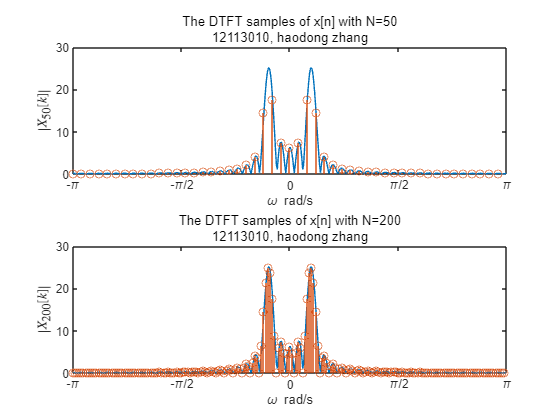

figure;
N = 50;
x = zeros(1,N);
for n = 0:49
    x(n+1) = sin(0.1*pi*n);
end
[X,w] = DTFTsamples(x);
[X2,W] = DTFT(x,512);
subplot(2,1,1);
plot(W,abs(X2));
hold on
stem(w,abs(X));
hold off
title(sprintf('The DTFT samples of x[n] with N=50\n12113010, haodong zhang'))
xlabel('\omega rad/s');
ylabel('$\left | X_{50}[k]  \right | $', 'Interpreter', 'latex')
xlim([-pi,pi])
xticks([-pi -pi/2 0 pi/2 pi]);
xticklabels({'-\pi' '-\pi/2' '0' '\pi/2' '\pi'});

N = 200;
x = zeros(1,N);
for n = 0:49
    x(n+1) = sin(0.1*pi*n);
end
[X,w] = DTFTsamples(x);
subplot(2,1,2);
plot(W,abs(X2));
hold on
stem(w,abs(X));
hold off
title(sprintf('The DTFT samples of x[n] with N=200\n12113010, haodong zhang'))
xlabel('\omega rad/s');
ylabel('$\left | X_{200}[k]  \right | $', 'Interpreter', 'latex')
xlim([-pi,pi])
xticks([-pi -pi/2 0 pi/2 pi]);
xticklabels({'-\pi' '-\pi/2' '0' '\pi/2' '\pi'});

5.3.1

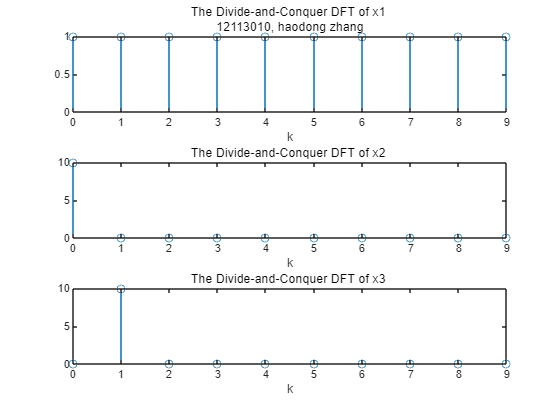

figure;
n = -5:4;
k=0:9;
x1 = (n==0);
X1 = dcDFT(x1);
x2 = ones(1,10);
X2 = dcDFT(x2);
x3 = exp(1j*2*pi*n/10);
X3 = dcDFT(x3);
subplot(3,1,1)
stem(k,abs(X1));
title(sprintf('The Divide-and-Conquer DFT of x1 \n12113010, haodong zhang'))
xlabel('k');
subplot(3,1,2)
stem(k,abs(X2));
title(sprintf('The Divide-and-Conquer DFT of x2 '))
xlabel('k');
subplot(3,1,3)
stem(k,abs(X3));
title(sprintf('The Divide-and-Conquer DFT of x3 '))
xlabel('k');

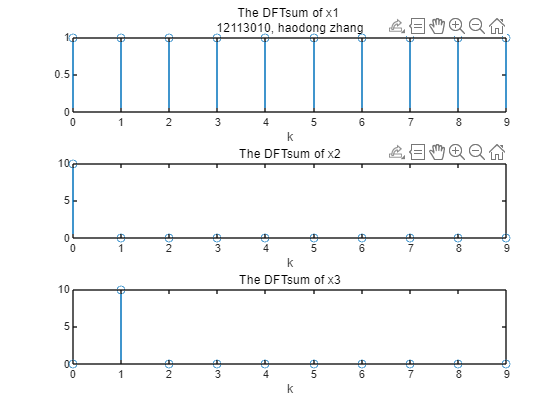

figure;
X11 = DFTsum(x1);
X22 = DFTsum(x2);
X33 = DFTsum(x3);
subplot(3,1,1)
stem(k,abs(X11));
title(sprintf('The DFTsum of x1 \n12113010, haodong zhang'))
xlabel('k');
subplot(3,1,2)
stem(k,abs(X22));
title(sprintf('The DFTsum of x2'))
xlabel('k');
subplot(3,1,3)
stem(k,abs(X33));
title(sprintf('The DFTsum of x3'))
xlabel('k');

5.3.2

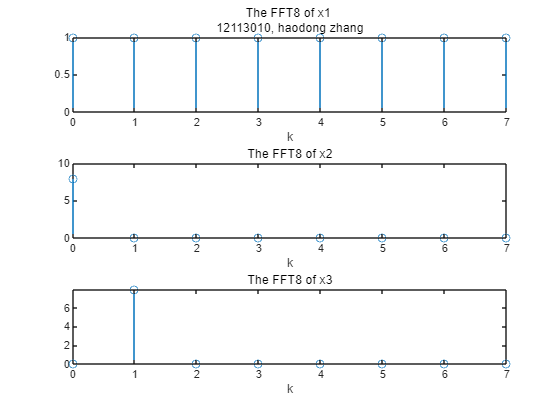

figure;
n = -3:4;
k=0:7;
x1 = (n==0);
X1 = FFT8(x1);
x2 = ones(1,8);
X2 = FFT8(x2);
x3 = exp(1j*2*pi*n/8);
X3 = FFT8(x3);
subplot(3,1,1)
stem(k,abs(X1));
title(sprintf('The FFT8 of x1 \n12113010, haodong zhang'))
xlabel('k');
subplot(3,1,2)
stem(k,abs(X2));
title(sprintf('The FFT8 of x2'))
xlabel('k');
subplot(3,1,3)
stem(k,abs(X3));
title(sprintf('The FFT8 of x3'))
xlabel('k');

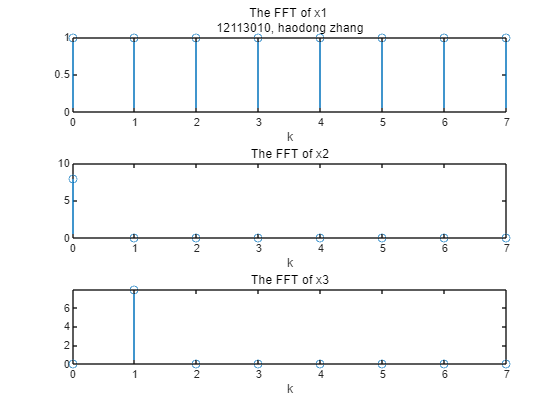

figure;
n = -3:4;
k=0:7;
x1 = (n==0);
X1 = fft_stage(x1);
x2 = ones(1,8);
X2 = fft_stage(x2);
x3 = exp(1j*2*pi*n/8);
X3 = fft_stage(x3);
subplot(3,1,1)
stem(k,abs(X1));
title(sprintf('The FFT of x1 \n12113010, haodong zhang'))
xlabel('k');
subplot(3,1,2)
stem(k,abs(X2));
title(sprintf('The FFT of x2'))
xlabel('k');
subplot(3,1,3)
stem(k,abs(X3));
title(sprintf('The FFT of x3'))
xlabel('k');